# Running Mean Time Series Filter

- y(t) = 1/(2k + 1) * sum(x(i)) i=t-k to t+k

**create signal**

freq = 1000; %hz
t    = 0:(1/freq):10; %sample signal for 10 seconds
n    = length(t);
p    = 12; % for random interpolation

noise = 4;
sigc  = interp1(rand(p,1)*24, linspace(1,p,n));
noise = noise * randn(size(t));
sign  = sigc + noise;

**plot the signals**

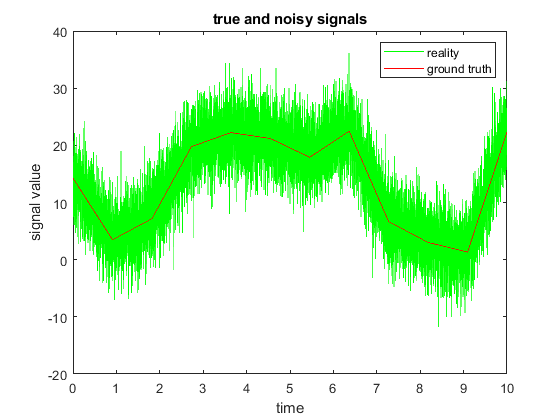

noisy = plot(t, sign, 'g');
hold on;
true = plot(t, sigc, 'r-');
hold off;
title("true and noisy signals");
xlabel("time");
ylabel("signal value");
legend([noisy,true], ["reality", "ground truth"]);

**Implement the running mean filter**

filtered = sign;
k = 20; % number of data points for the sliding window
ms = 1000*(k*2+1) / freq; % sliding window in ms
disp(ms);

    41



for i = k+1:n-k-1 %cant start at zero because there is nothing prior to average
    filtered(i) = mean(sign(i-k:i+k));
end

**Plot the filtered signal and sliding window**

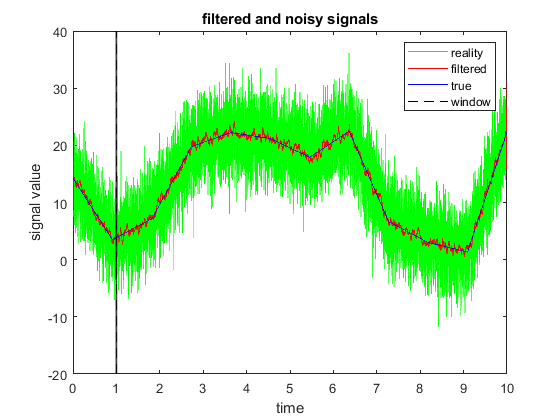

figure(1);
noisy = plot(t, sign, 'g');
hold on;
filtered = plot(t, filtered, 'r-');
true = plot(t, sigc, 'b-');
% draw window
tx = dsearchn(t',1);
ylim = get(gca,'ylim');
patch(t([ tx-k tx-k tx+k tx+k ]),ylim([ 1 2 2 1 ]),'k','facealpha',.75,'linestyle','none');
window = plot(t([tx tx]),ylim,'k--');
hold off;
title("filtered and noisy signals");
xlabel("time");
ylabel("signal value");
legend([noisy,filtered, true, window], ["reality", "filtered", "true", "window"]);